# **Week 5 : Examining PMD Insertion and Equalization using CMA**

The code below examines the ability of digital optical systems to use adaptive equalization to rectify the distortion introduced by polarization-mode dispersion using the constant modulus algorithm when BPSK and QPSK are used as modulation formats

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

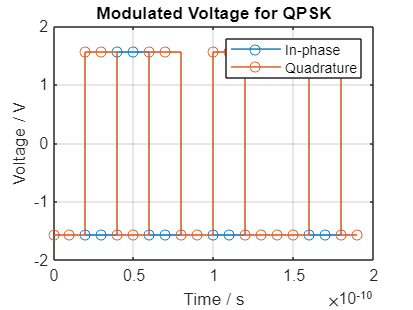

clear all; clearvars;

% Parameters
NSymb = 150000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
T = 1/(SpS*Rs); % Sampling period in s
t= [0:1:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevels = [-pi/2, pi/2]'; % Discrete voltage levels for BPSK and QPSK
% voltageLevelsQAM = [-3*pi/16, -pi/16, pi/16, 3*pi/16]'; % Discrete voltages for QAM
voltageLevelsQAM = [asin(-3/sqrt(10)), asin(-1/sqrt(10)), asin(1/sqrt(10)), asin(3/sqrt(10))]';
DCOffset = 0; % DC offset of modulated current in V

% -------------------------------------------------------------------------------

% FOR BPSK:
% Generating random bit sequence(s)
% sourceBitsBPSK = randi([0 1], NSymb, 2); % Matrix of source bits for BPSK
% sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
% vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));
% 
% vI_BPSK(real(sourceSymbolsBPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
% vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevels(1); % Maps -1 -pi/2
% 
% vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
% vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase voltage
% stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltages for BPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, 2); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/2
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/2

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage for QPSK")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

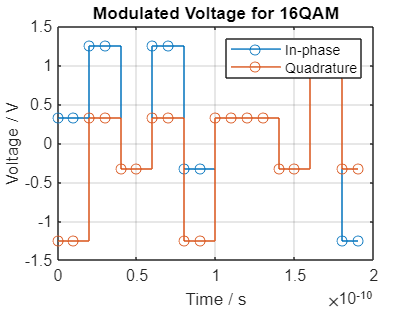


% -----------------------------------------

% For 16QAM
sourceBitsQAM = randi([0 1], NSymb*4, 2); % Matrix of source bits for 16QAM
sourceIntsQAM = bit2int(sourceBitsQAM, 4); % Vector of source bits converted to ints
sourceSymbolsQAM = qammod(sourceIntsQAM, 16, UnitAveragePower=true); % Maps source bit vector to symbol vector

% Modulating voltage with generated symbols
vI_QAM = ones(size(sourceSymbolsQAM)); vQ_QAM = zeros(size(sourceSymbolsQAM));

QAMBoundaries = [-2/sqrt(10), 0, 2/sqrt(10)];

vI_QAM(real(sourceSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vI_QAM(real(sourceSymbolsQAM)>-2/sqrt(10) & real(sourceSymbolsQAM)<=0) = voltageLevelsQAM(2);
vI_QAM(real(sourceSymbolsQAM)>0 & real(sourceSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vI_QAM(real(sourceSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vQ_QAM(imag(sourceSymbolsQAM)<=-2/sqrt(10)) = voltageLevelsQAM(1); 
vQ_QAM(imag(sourceSymbolsQAM)>-2/sqrt(10) & imag(sourceSymbolsQAM)<=0) = voltageLevelsQAM(2);
vQ_QAM(imag(sourceSymbolsQAM)>0 & imag(sourceSymbolsQAM)<=2/sqrt(10)) = voltageLevelsQAM(3); 
vQ_QAM(imag(sourceSymbolsQAM)>2/sqrt(10)) = voltageLevelsQAM(4); 

vI_QAM_upsampled = repelem(vI_QAM, SpS, 1); % Upsampling according to SpS
vQ_QAM_upsampled = repelem(vQ_QAM, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QAM_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QAM_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage for 16QAM")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### Pulse Shaping

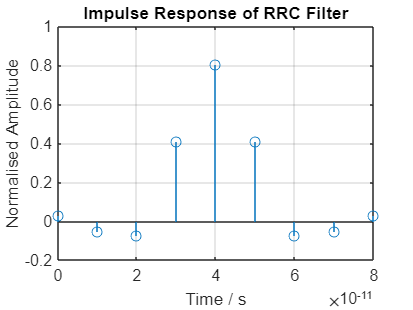

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

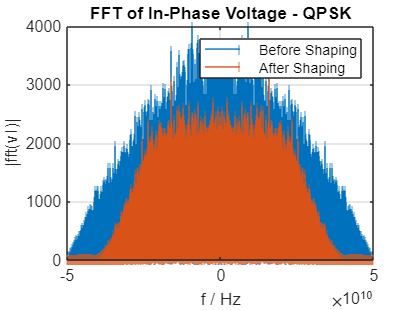


% ---------------------------------------------------------------------------

% FOR BPSK:
% Using RRC filter to shape vI and vQ
% vI_BPSK_shaped = upfirdn(vI_BPSK, filterResponse, SpS, 1); vQ_BPSK_shaped = upfirdn(vQ_BPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before and after filtering
% fft_vI_BPSK = fftshift(fft(vI_BPSK_upsampled(:,1))); % FFT of noisy signal before shaping 
% freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
% 
% fft_vI_BPSK_shaped = fftshift(fft(vI_BPSK_shaped(:,1))); % FFT of noisy signal after shaping
% freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);
% 
% stem(freqArr, abs(fft_vI_BPSK), "|");
% hold on
% stem(freqArr_shaped, abs(fft_vI_BPSK_shaped), "|");
% title("FFT of In-Phase Voltage - BPSK");
% xlabel("f / Hz");
% ylabel("|fft(vI)|");
% legend("Before Shaping", "After Shaping")
% hold off
% grid on

% Visualising pulse-shaped voltages
% stairs(v_shaped_t(1:10*SpS + filterSpan), vI_BPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_BPSK_shaped(1:10*SpS + filterSpan,1), "o-");
% title("Shaped In-Phase Voltage - BPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After Shaping");
% grid on
% hold off

% -------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ
vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(vI_QPSK_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on

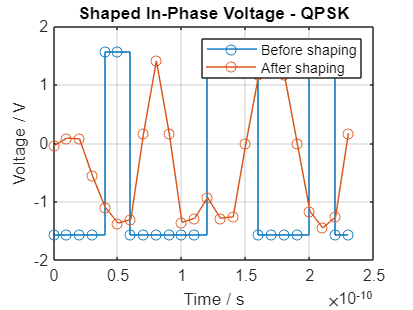


% Visualising pulse-shaped voltages
stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_upsampled(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - QPSK");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After shaping");
grid on
hold off

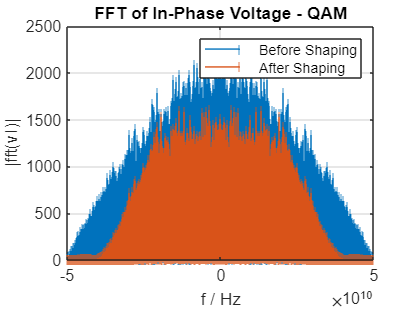



% -------------------------------------------------------------------------

% FOR 16-QAM:
% Using RRC filter to shape vI and vQ
vI_QAM_shaped = upfirdn(vI_QAM, filterResponse, SpS, 1); vQ_QAM_shaped = upfirdn(vQ_QAM, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QAM = fftshift(fft(vI_QAM_upsampled(:,1))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QAM_shaped = fftshift(fft(vI_QAM_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QAM), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QAM_shaped), "|");
title("FFT of In-Phase Voltage - QAM");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on

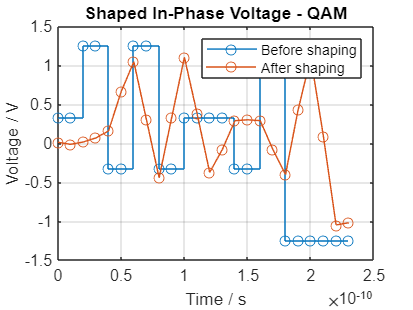


% Visualising pulse-shaped voltages
stairs(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_upsampled(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QAM_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - QAM");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After shaping");
grid on
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### IQ Modulation

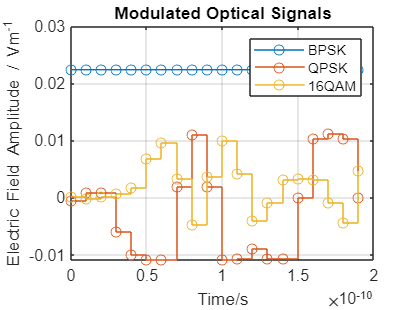

% Initialising laser parameters
lineWidth = 0;
laserPw_dBm = 0;
laserPw_Lin = 1e-3*10^(laserPw_dBm/10);

% Generating output from laser modelled as a contniuous-wave source
laserE = Laser(laserPw_dBm, lineWidth, SpS, Rs, NSymb, 2); % Laser output to be used with unshaped signals
laserE_shaped = Laser(laserPw_dBm, lineWidth, SpS, Rs, samples/SpS, 2); % Laser output to be used with shaped signals

% Visualising output from laser
plot(t(1:20), real(laserE(1:20)), "o-");
title("Laser Output as a Continous Wave");
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}");
grid on

% Modulating optical signal using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

% modOpticSigBPSK = IQModulatorModified(vI_BPSK_upsampled, vQ_BPSK_upsampled, laserE, Vpi);
% modOpticSigQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi); % Unshaped
% modOpticSigQAM = IQModulatorModified(vI_QAM_upsampled, vQ_QAM_upsampled, laserE, Vpi); % Unshaped

modOpticSigQPSK = IQModulatorModified(vI_QPSK_shaped, vQ_QPSK_shaped, laserE_shaped, Vpi); % Unshaped
modOpticSigQAM = IQModulatorModified(vI_QAM_shaped, vQ_QAM_shaped, laserE_shaped, Vpi); % Unshaped

% Visualising modulated optical signals
% stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,1)), "o-");
hold on
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,1)), "o-");
stairs(t(1:10*SpS), real(modOpticSigQAM(1:10*SpS,1)), "o-");
title("Modulated Optical Signals")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("BPSK", "QPSK", "16QAM")
grid on
hold off

## Optical Channel

### Adding PMD

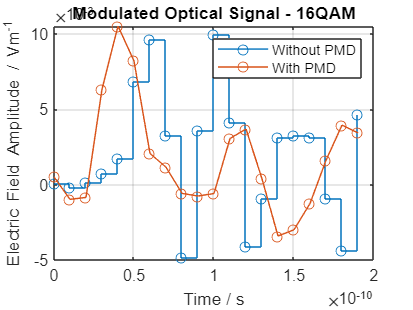

DGD_mean = 0.1; % Mean differential group delay in ps/sqrt(km)
linkLength = 50e3; % Fibre length in metres
N = 10; % Number of birefringent elements 

% [modOpticSigBPSK_PMD, BPSK_tau] = PMDInsertion(modOpticSigBPSK, DGD_mean, linkLength, N, Rs, SpS, true);
[modOpticSigQPSK_PMD, QPSK_tau] = PMDInsertion(modOpticSigQPSK, DGD_mean, linkLength, N, Rs, SpS, true);
[modOpticSigQAM_PMD, QAM_tau] = PMDInsertion(modOpticSigQAM, DGD_mean, linkLength, N, Rs, SpS, true);

% Visualising optical signal before and after PMD insertion for BPSK:
% stairs(t(1:10*SpS), abs(modOpticSigBPSK(1:10*SpS,1)).*cos(angle(modOpticSigBPSK(1:10*SpS,1))), "-o"); 
% hold on
% plot(t(1:10*SpS), abs(modOpticSigBPSK_PMD(1:10*SpS,1)).*cos(angle(modOpticSigBPSK_PMD(1:10*SpS,1))), "-o");
% xlabel("Time / s"); 
% ylabel("Electric Field Amplitude / Vm^{-1}")
% title("Modulated Optical Signal - BPSK")
% legend("Without PMD", "With PMD")
% grid on
% hold off

% Visualising optical signal before and after PMD insertion:
stairs(t(1:10*SpS), abs(modOpticSigQAM(1:10*SpS,1)).*cos(angle(modOpticSigQAM(1:10*SpS,1))), "-o"); 
hold on
plot(t(1:10*SpS), abs(modOpticSigQAM_PMD(1:10*SpS,1)).*cos(angle(modOpticSigQAM_PMD(1:10*SpS,1))), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal - 16QAM")
legend("Without PMD", "With PMD")
grid on
hold off

## Receiver

### Optical Front-End

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped;

% Visualising locally generated optical signal
% plot(t(1:20), real(Elo(1:20,1)), "o");
% title("Locally Generated Optical Signal");
% xlabel("Time/s")
% ylabel("Electric Field Amplitude/ Vm^{-1}")
% grid on

% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

% Signals with PMD
% OpticFEOutBPSK = OpticalFrontEnd(modOpticSigBPSK_PMD, Elo, eta_ph, 2);
OpticFEOutQPSK = OpticalFrontEnd(modOpticSigQPSK_PMD, Elo_shaped, eta_ph, 2);
OpticFEOutQAM = OpticalFrontEnd(modOpticSigQAM_PMD, Elo_shaped, eta_ph, 2);

% Test signals with no added PMD
% testFEOutBPSK = OpticalFrontEnd(modOpticSigBPSK, Elo, eta_ph, 2);
testFEOutQPSK = OpticalFrontEnd(modOpticSigQPSK, Elo_shaped, eta_ph, 2);
testFEOutQAM = OpticalFrontEnd(modOpticSigQAM, Elo_shaped, eta_ph, 2);

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components of the two polarizations
% BPSK
% OpticFEOutBPSK_IV = TIA_Gain*OpticFEOutBPSK(:,1); OpticFEOutBPSK_QV = TIA_Gain*OpticFEOutBPSK(:,2); % With PMD
% OpticFEOutBPSK_IH = TIA_Gain*OpticFEOutBPSK(:,3); OpticFEOutBPSK_QH = TIA_Gain*OpticFEOutBPSK(:,4); % With PMD

% testFEOutBPSK_IV = TIA_Gain*testFEOutBPSK(:,1); testFEOutBPSK_QV = TIA_Gain*testFEOutBPSK(:,2); % Without PMD
% testFEOutBPSK_IH = TIA_Gain*testFEOutBPSK(:,3); testFEOutBPSK_QH = TIA_Gain*testFEOutBPSK(:,4); % Without PMD

% QPSK
OpticFEOutQPSK_IV = TIA_Gain*OpticFEOutQPSK(:,1); OpticFEOutQPSK_QV = TIA_Gain*OpticFEOutQPSK(:,2); % With PMD
OpticFEOutQPSK_IH = TIA_Gain*OpticFEOutQPSK(:,3); OpticFEOutQPSK_QH = TIA_Gain*OpticFEOutQPSK(:,4); % With PMD

testFEOutQPSK_IV = TIA_Gain*testFEOutQPSK(:,1); testFEOutQPSK_QV = TIA_Gain*testFEOutQPSK(:,2); % Without PMD
testFEOutQPSK_IH = TIA_Gain*testFEOutQPSK(:,3); testFEOutQPSK_QH = TIA_Gain*testFEOutQPSK(:,4); % Without PMD

% 16-QAM
OpticFEOutQAM_IV = TIA_Gain*OpticFEOutQAM(:,1); OpticFEOutQAM_QV = TIA_Gain*OpticFEOutQAM(:,2); % With PMD
OpticFEOutQAM_IH = TIA_Gain*OpticFEOutQAM(:,3); OpticFEOutQAM_QH = TIA_Gain*OpticFEOutQAM(:,4); % With PMD

testFEOutQAM_IV = TIA_Gain*testFEOutQAM(:,1); testFEOutQAM_QV = TIA_Gain*testFEOutQAM(:,2); % Without PMD
testFEOutQAM_IH = TIA_Gain*testFEOutQAM(:,3); testFEOutQAM_QH = TIA_Gain*testFEOutQAM(:,4); % Without PMD


## DSP

### Scaling and Downsampling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor=1;
scaleFactor = 0.5*TIA_Gain*eta_ph*laserEMag*laserEMag/2;

% Cancelling the scaling factor:
% BPSK
% voltageBPSK_IV = OpticFEOutBPSK_IV/scaleFactor; voltageBPSK_QV = OpticFEOutBPSK_QV/scaleFactor; % With PMD
% voltageBPSK_IH = OpticFEOutBPSK_IH/scaleFactor; voltageBPSK_QH = OpticFEOutBPSK_QH/scaleFactor; % With PMD

% testBPSK_IV = testFEOutBPSK_IV(1:SpS:end)/scaleFactor; testBPSK_QV = testFEOutBPSK_QV(1:SpS:end)/scaleFactor; % Without PMD
% testBPSK_IH = testFEOutBPSK_IH(1:SpS:end)/scaleFactor; testBPSK_QH = testFEOutBPSK_QH(1:SpS:end)/scaleFactor; % Without PMD

% QPSK
voltageQPSK_IV = OpticFEOutQPSK_IV/scaleFactor; voltageQPSK_QV = OpticFEOutQPSK_QV/scaleFactor; % With PMD
voltageQPSK_IH = OpticFEOutQPSK_IH/scaleFactor; voltageQPSK_QH = OpticFEOutQPSK_QH/scaleFactor; % With PMD

testQPSK_IV = testFEOutQPSK_IV/scaleFactor; testQPSK_QV = testFEOutQPSK_QV/scaleFactor; % Without PMD
testQPSK_IH = testFEOutQPSK_IH/scaleFactor; testQPSK_QH = testFEOutQPSK_QH/scaleFactor; % Without PMD

% 16-QAM
voltageQAM_IV = OpticFEOutQAM_IV/scaleFactor; voltageQAM_QV = OpticFEOutQAM_QV/scaleFactor; % With PMD
voltageQAM_IH = OpticFEOutQAM_IH/scaleFactor; voltageQAM_QH = OpticFEOutQAM_QH/scaleFactor; % With PMD

testQAM_IV = testFEOutQAM_IV/scaleFactor; testQAM_QV = testFEOutQAM_QV/scaleFactor; % Without PMD
testQAM_IH = testFEOutQAM_IH/scaleFactor; testQAM_QH = testFEOutQAM_QH/scaleFactor; % Without PMD

### Adaptive Equalization

% Equalization parameters:
R_CMA = 1; % Reference radius = 1 for constant modulus alphabets
NTaps = 3; % Length of each FIR filter in the 2x2 butterfly MIMO

% Step size in the gradient descent algorithm
Mu_BPSK = 0.08; Mu_QPSK = 0.005; Mu_QAM = 0.0001;

% Number of coefficient calculations after which filters w2H and w2V are initialised
N1_BPSK = 1000; N1_QPSK = 10000; N1_QAM = 10000; N2_QAM = 20000;

% Number of symbols to discard from the output
NRemove_BPSK = 40000; NRemove_QPSK = 80000; NRemove_QAM = 80000;

% Inputs to adaptive equalizer:
% BPSK_xV = voltageBPSK_IV + 1i*voltageBPSK_QV; BPSK_xH = voltageBPSK_IH + 1i*voltageBPSK_QH; % BPSK
QPSK_xV = voltageQPSK_IV + 1i*voltageQPSK_QV; QPSK_xH = voltageQPSK_IH + 1i*voltageQPSK_QH; % QPSK
QAM_xV = voltageQAM_IV + 1i*voltageQAM_QV; QAM_xH = voltageQAM_IH + 1i*voltageQAM_QH; % 16QAM

% Apaptive equalization using the CMA/RDE algorithm
% [BPSK_Eq,BPSK_w1V,BPSK_w1H,BPSK_w2V,BPSK_w2H] = AdapEqualizerCMA([BPSK_xV BPSK_xH], SpS, NTaps, Mu_BPSK, true, N1_BPSK, 0);
[QPSK_Eq_Adap,QPSK_w1V,QPSK_w1H,QPSK_w2V,QPSK_w2H] = AdapEqualizerCMA([QPSK_xV QPSK_xH], SpS, NTaps, Mu_QPSK, true, N1_QPSK, 0);
[QAM_Eq_Adap,QAM_w1V,QAM_w1H,QAM_w2V,QAM_w2H] = AdapEqualizerRDE([QAM_xV QAM_xH], SpS, NTaps, Mu_QAM, true, N1_QAM, N2_QAM, 0);

### Matched Filtering

% Filtering QPSK
% Equalised Symbols
QPSK_Eq_I = upfirdn(real(QPSK_Eq_Adap), rcosdesign(rollOff, filterSpan, 1), 1, 1); QPSK_Eq_I = QPSK_Eq_I(filterSpan + 1:end - filterSpan+1,:);
QPSK_Eq_Q = upfirdn(imag(QPSK_Eq_Adap), rcosdesign(rollOff, filterSpan, 1), 1, 1); QPSK_Eq_Q = QPSK_Eq_Q(filterSpan + 1:end - filterSpan+1,:);
QPSK_Eq = QPSK_Eq_I + 1i*QPSK_Eq_Q;

% Test Symbols
testQPSK_I = upfirdn([testQPSK_IV testQPSK_IH], filterResponse, 1, 2); testQPSK_I = testQPSK_I(filterSpan + 1:end - filterSpan,:);
testQPSK_Q = upfirdn([testQPSK_QV testQPSK_QH], filterResponse, 1, 2); testQPSK_Q = testQPSK_Q(filterSpan + 1:end - filterSpan,:);

% Filtering 16-QAM
% Equalized Symbols
QAM_Eq_I = upfirdn(real(QAM_Eq_Adap), rcosdesign(rollOff, filterSpan, 1), 1, 1); QAM_Eq_I = QAM_Eq_I(filterSpan + 1:end - filterSpan+1,:);
QAM_Eq_Q = upfirdn(imag(QAM_Eq_Adap), rcosdesign(rollOff, filterSpan, 1), 1, 1); QAM_Eq_Q = QAM_Eq_Q(filterSpan + 1:end - filterSpan+1,:);
QAM_Eq = QAM_Eq_I + 1i*QAM_Eq_Q;

% Test Symbols
testQAM_I = upfirdn([testQAM_IV testQAM_IH], filterResponse, 1, 2); testQAM_I = testQAM_I(filterSpan + 1:end - filterSpan,:);
testQAM_Q = upfirdn([testQAM_QV testQAM_QH], filterResponse, 1, 2); testQAM_Q = testQAM_Q(filterSpan + 1:end - filterSpan,:);


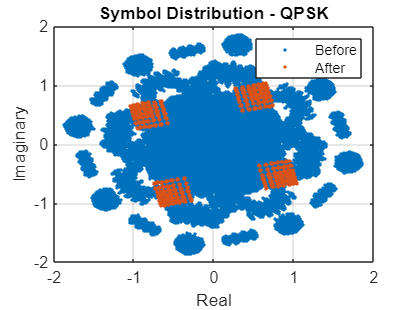

% Visualisation of symbol distribution before and after equalisation
% plot(BPSK_xV, '.');
% hold on
% plot(BPSK_Eq(:,1), '.');
% title("Symbol Distribution - BPSK")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before", "After")
% grid on
% hold off

plot(QPSK_xV, '.');
hold on
plot(QPSK_Eq(NRemove_QPSK:end,1), '.');
title("Symbol Distribution - QPSK")
xlabel("Real")
ylabel("Imaginary")
legend("Before", "After")
grid on
hold off

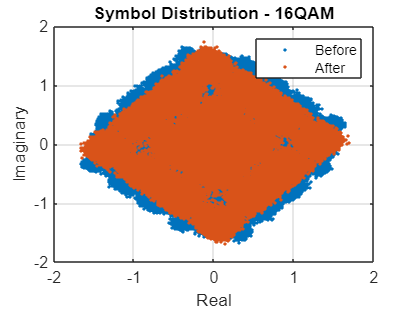


plot(QAM_xV, '.');
hold on
plot(QAM_Eq(NRemove_QAM:end,1), '.');
title("Symbol Distribution - 16QAM")
xlabel("Real")
ylabel("Imaginary")
legend("Before", "After")
grid on
hold off

% Visualisation of filter coefficient variation - BPSK
% Visualisation of variation of filter coefficients
% plot([1:size(BPSK_w1V,2)], BPSK_w1V', '-', lineWidth=2);
% title("BPSK Filter Coefficient Variation - w_{1V}")
% xlabel("Symbol Index")
% ylabel("Value")
% legend("Tap 1", "Tap 2", "Tap 3")
% grid on
% hold off

% Visualisation of variation of filter coefficients
% plot([1:size(BPSK_w1H,2)], BPSK_w1H', '-', lineWidth=2);
% title("BPSK Filter Coefficient Variation - w_{1H}")
% xlabel("Symbol Index")
% ylabel("Value")
% legend("Tap 1", "Tap 2", "Tap 3")
% grid on
% hold off

% Visualisation of variation of filter coefficients
% plot([1:size(BPSK_w2V,2)], BPSK_w2V', '-', lineWidth=2);
% title("BPSK Filter Coefficient Variation - w_{2V}")
% xlabel("Symbol Index")
% ylabel("Value")
% legend("Tap 1", "Tap 2", "Tap 3")
% grid on
% hold off

% Visualisation of variation of filter coefficients
% plot([1:size(BPSK_w2H,2)], BPSK_w2H', '-', lineWidth=2);
% title("BPSK Filter Coefficient Variation - w_{2H}")
% xlabel("Symbol Index")
% ylabel("Value")
% legend("Tap 1", "Tap 2", "Tap 3")
% grid on
% hold off


% Visualisation of filter coefficient variation - QPSK
% Visualisation of variation of filter coefficients
plot([1:size(QPSK_w1V,2)], QPSK_w1V', '-', lineWidth=5);

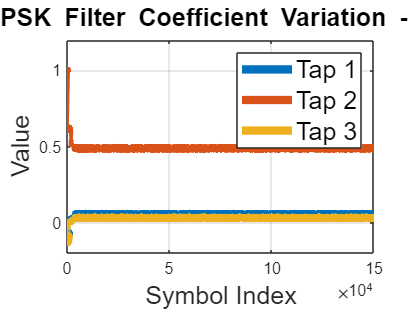

title("QPSK Filter Coefficient Variation - w_{1V}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QPSK_w1H,2)], QPSK_w1H', '-', lineWidth=5);

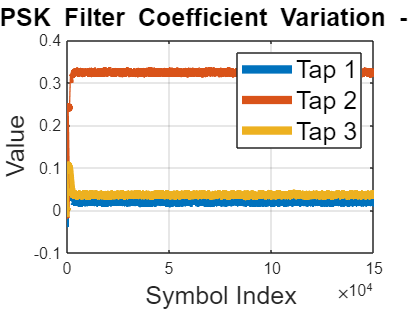

title("QPSK Filter Coefficient Variation - w_{1H}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QPSK_w2V,2)], QPSK_w2V', '-', lineWidth=5);

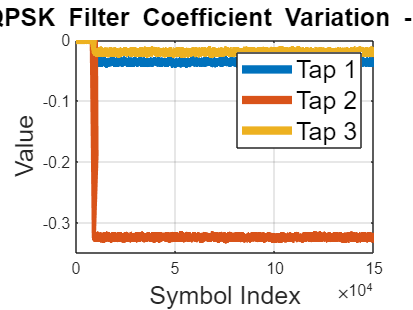

title("QPSK Filter Coefficient Variation - w_{2V}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QPSK_w2H,2)], QPSK_w2H', '-', lineWidth=5);

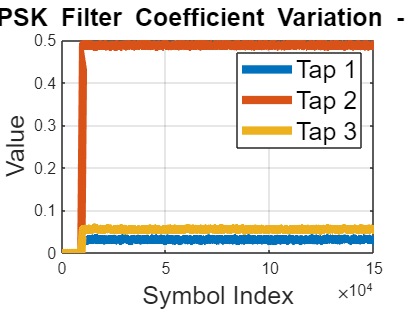

title("QPSK Filter Coefficient Variation - w_{2H}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off

% Visualisation of filter coefficient variation - 16QAM
% Visualisation of variation of filter coefficients
plot([1:size(QAM_w1V,2)], QAM_w1V', '-', lineWidth=5);

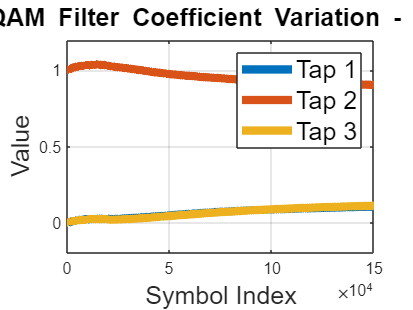

title("QAM Filter Coefficient Variation - w_{1V}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QAM_w1H,2)], QAM_w1H', '-', lineWidth=5);

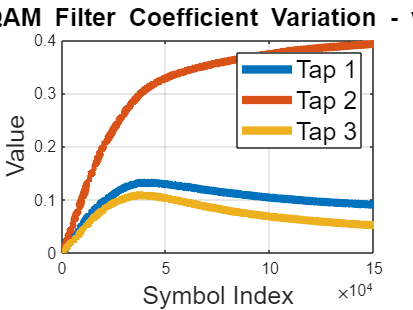

title("QAM Filter Coefficient Variation - w_{1H}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QAM_w2V,2)], QAM_w2V', '-', lineWidth=5);

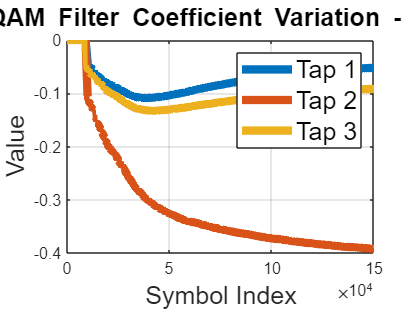

title("QAM Filter Coefficient Variation - w_{2V}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off


% Visualisation of variation of filter coefficients
plot([1:size(QAM_w2H,2)], QAM_w2H', '-', lineWidth=5);

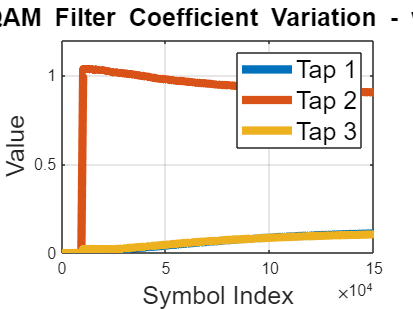

title("QAM Filter Coefficient Variation - w_{2H}", FontSize=15)
xlabel("Symbol Index", FontSize=15)
ylabel("Value", FontSize=15)
legend("Tap 1", "Tap 2", "Tap 3", FontSize=15)
grid on
hold off

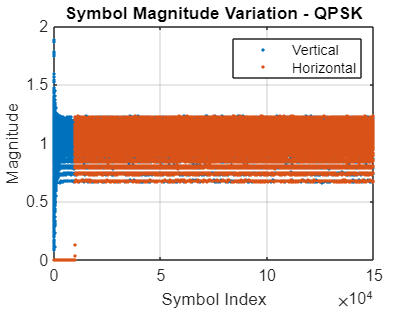

% Visualising output symbol magnitudes
% plot([1:size(BPSK_Eq,1)], abs(BPSK_Eq(:,1)), '.')
% hold on
% plot([1:size(BPSK_Eq,1)], abs(BPSK_Eq(:,2)), '.')
% title("Symbol Magnitude Variation - BPSK")
% xlabel("Symbol Index")
% ylabel("Magnitude")
% legend("Vertical", "Horizontal")
% grid on
% hold off

plot([1:size(QPSK_Eq,1)], abs(QPSK_Eq(:,1)), '.')
hold on
plot([1:size(QPSK_Eq,1)], abs(QPSK_Eq(:,2)), '.')
title("Symbol Magnitude Variation - QPSK")
xlabel("Symbol Index")
ylabel("Magnitude")
legend("Vertical", "Horizontal")
grid on
hold off

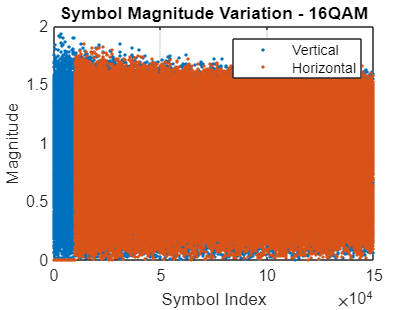


plot([1:size(QAM_Eq,1)], abs(QAM_Eq(:,1)), '.')
hold on
plot([1:size(QAM_Eq,1)], abs(QAM_Eq(:,2)), '.')
title("Symbol Magnitude Variation - 16QAM")
xlabel("Symbol Index")
ylabel("Magnitude")
legend("Vertical", "Horizontal")
grid on
hold off

### Decoding and Decision

% BPSK
% Before Equalization
% BPSK_y_PMD = [BPSK_xV(1:SpS:end) BPSK_xH(1:SpS:end)];
% decodedSymbolsBPSK_PMD = ones(size(BPSK_y_PMD)); 
% decodedSymbolsBPSK_PMD(real(BPSK_y_PMD) > 0) = 1; decodedSymbolsBPSK_PMD(real(BPSK_y_PMD) <= 0) = -1;
% decodedIntsBPSK_PMD = pskdemod(decodedSymbolsBPSK_PMD, 2);
% decodedBitsBPSK_PMD = int2bit(decodedIntsBPSK_PMD, 1);

% After Equalization
% decodedSymbolsBPSK = BPSK_Eq;
% decodedIntsBPSK = pskdemod(decodedSymbolsBPSK, 2);
% decodedBitsBPSK = int2bit(decodedIntsBPSK, 1);

% [decodedBitsBPSK, testBER_BPSK] = CMAPhaseCompensator("BPSK", sourceBitsBPSK(1+NRemove_BPSK:end,:), BPSK_Eq(1+NRemove_BPSK:end,:), 0);
% testBER_BPSK

% Test 
% testSymbolsBPSK = ones(size([testBPSK_IV testBPSK_IH])); 
% testSymbolsBPSK([testBPSK_IV testBPSK_IH]> 0) = 1; testSymbolsBPSK([testBPSK_IV testBPSK_IH] <= 0) = -1;
% testIntsBPSK = pskdemod(testSymbolsBPSK, 2);
% testBitsBPSK = int2bit(testIntsBPSK, 1);
% biterr(testBitsBPSK, sourceBitsBPSK)

% --------------------------------------------------------------------------------------------

% QPSK
% Before Equalization
QPSK_y_PMD = [QPSK_xV(1:SpS:end) QPSK_xH(1:SpS:end)];
decodedSymbolsQPSK_PMD = ones(size(QPSK_y_PMD)); 
decodedIntsQPSK_PMD = pskdemod(decodedSymbolsQPSK_PMD, 4, pi/4);
decodedBitsQPSK_PMD = int2bit(decodedIntsQPSK_PMD, 2);

% After Equalization
decodedSymbolsQPSK = QPSK_Eq;
decodedIntsQPSK = pskdemod(decodedSymbolsQPSK, 4, pi/4);
[decodedBitsQPSK, testBER_QPSK] = CMAPhaseCompensator("QPSK", sourceBitsQPSK(1+NRemove_QPSK*2:end,:), QPSK_Eq(1+NRemove_QPSK:end,:), pi/4);
testBER_QPSK

testBER_QPSK =     0.5010
    0.5002



% Phase Recovery after PMD compensation
% BPSParams = struct("B", 4, "N", 10, "PEstimate", false); % BPS parameters
% decodedSymbolsQPSK_BPS = BPS(decodedSymbolsQPSK, 4, 2, BPSParams);
% decodedIntsQPSK_BPS = pskdemod(decodedSymbolsQPSK_BPS, 4, pi/4);
% decodedBitsQPSK_BPS = int2bit(decodedIntsQPSK_BPS, 2);

% Visualising effect of BPS
% plot(decodedSymbolsQPSK(1+NRemove_QPSK*2:end,1), '.')
% hold on
% plot(decodedSymbolsQPSK_BPS(1+NRemove_QPSK*2:end,1), '.')
% title("Symbol Distribution - QPSK")
% xlabel("Real")
% ylabel("Imaginary")
% legend("Before BPS", "After BPS")
% grid on
% hold off

% Test
testSymbolsQPSK = testQPSK_I+1i*testQPSK_Q;
testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
testBitsQPSK = int2bit(testIntsQPSK, 2);
biterr(testBitsQPSK, sourceBitsQPSK)

ans = 0

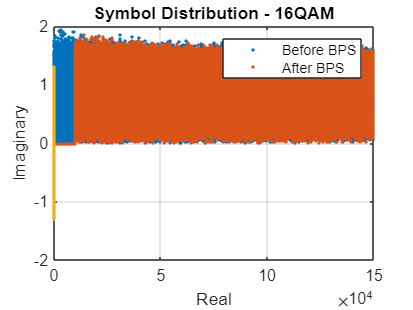


% --------------------------------------------------------------------------------------------

% 16QAM
% Before Equalization
QAM_y_PMD = [QAM_xV(1:SpS:end) QAM_xH(1:SpS:end)];
decodedSymbolsQAM_PMD = ones(size(QAM_y_PMD)); 
decodedIntsQAM_PMD = qamdemod(decodedSymbolsQAM_PMD, 16, UnitAveragePower=true);
decodedBitsQAM_PMD = int2bit(decodedIntsQAM_PMD, 4);

% After Equalization
decodedSymbolsQAM = QAM_Eq;
decodedIntsQAM = qamdemod(decodedSymbolsQAM, 16, UnitAveragePower=true);
decodedBitsQAM = int2bit(decodedIntsQAM, 4);

% Phase Recovery after PMD compensation
BPSParams = struct("B", 4, "N", 20, "PEstimate", false); % BPS parameters
decodedSymbolsQAM_BPS = BPS(decodedSymbolsQAM(1+NRemove_QAM:end,:), 16, 2, BPSParams);
decodedIntsQAM_BPS = qamdemod(decodedSymbolsQAM_BPS, 16, UnitAveragePower=true);
decodedBitsQAM_BPS = int2bit(decodedIntsQAM_BPS, 4);

% Visualising effect of BPS
plot(decodedSymbolsQAM(1+NRemove_QPSK*2:end,1), '.')
hold on
plot(decodedSymbolsQAM_BPS(:,1), '.')
title("Symbol Distribution - 16QAM")
xlabel("Real")
ylabel("Imaginary")
legend("Before BPS", "After BPS")
grid on
hold off


% Test
testSymbolsQAM = testQAM_I+1i*testQAM_Q;
testIntsQAM = qamdemod(testSymbolsQAM, 16, UnitAveragePower=true);
testBitsQAM = int2bit(testIntsQAM, 4);
biterr(testBitsQAM, sourceBitsQAM)

ans = 0

### Computing BER

for i=1:2
%     [~, BER_BPSK(i)] = biterr(decodedBitsBPSK(:,i), sourceBitsBPSK(1+NRemove_BPSK:end,i));
    [~, BER_QPSK(i)] = biterr(decodedBitsQPSK(:,i), sourceBitsQPSK(1+NRemove_QPSK*2:end,i));
    [~, BER_QAM(i)] = biterr(decodedBitsQAM(1+NRemove_QAM*4:end,i), sourceBitsQAM(1+NRemove_QAM*4:end,i));
    [~, BER_QAM_BPS(i)] = biterr(decodedBitsQAM_BPS(:,i), sourceBitsQAM(1+NRemove_QAM*4:end,i));
%     [~, BER_BPSK_PMD(i)] = biterr(decodedBitsBPSK_PMD, sourceBitsBPSK);
%     [~, BER_QPSK_PMD(i)] = biterr(decodedBitsQPSK_PMD, sourceBitsQPSK);
%     [~, BER_QAM_PMD(i)] = biterr(decodedBitsQAM_PMD, sourceBitsQAM);
end

% BER_BPSK
BER_QPSK

BER_QPSK =     0.5010    0.5002


BER_QAM

BER_QAM =     0.3443    0.4937


BER_QAM_BPS

BER_QAM_BPS =     0.0118    0.4937


% BER_BPSK_PMD
% BER_QPSK_PMD
% BER_QAM_PMD


% % Visualising variation of BER with link length
% plot(lengthSamples, BER_BPSK, "-o");
% hold on
% plot(lengthSamples, BER_QPSK, "-o");
% title("BER vs Link Length")
% xlabel("Link Length / km")
% ylabel("BER")
% legend("BPSK", "QPSK")
% grid on
% hold off